clc;clear;
% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf40_total.dat');
load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf40_total.mat")
load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF40_tx_bb.mat');

i = 2;
symbollen_table = [288, 576, 1152];
gilen_table = [32, 64, 128];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


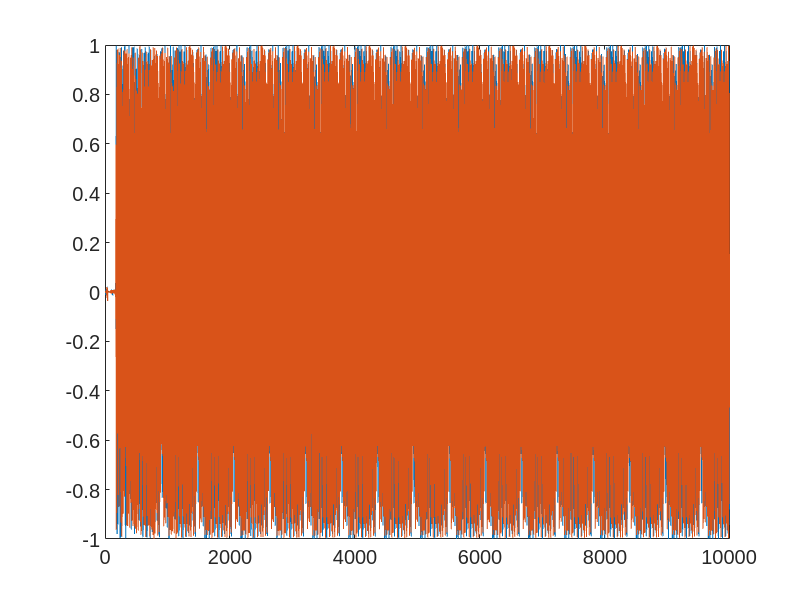

% time domain
N0 = 722;
figure
plot(real(data))
hold on
plot(imag(data))

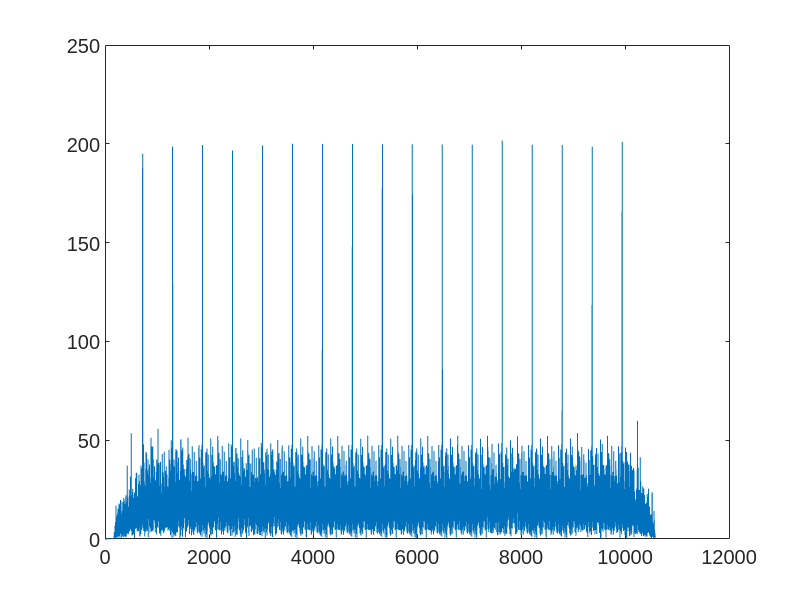

% plot(imag(data(N0+1:N0+288)))
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 


figure
corr_result = conv(data, bb(1,:));
plot(abs(corr_result))
hold on


figure()
Fs = 200e6;
t = 0:1/Fs:0.000001-1/Fs % 1000 points

t = 1.0e-06 *

         0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


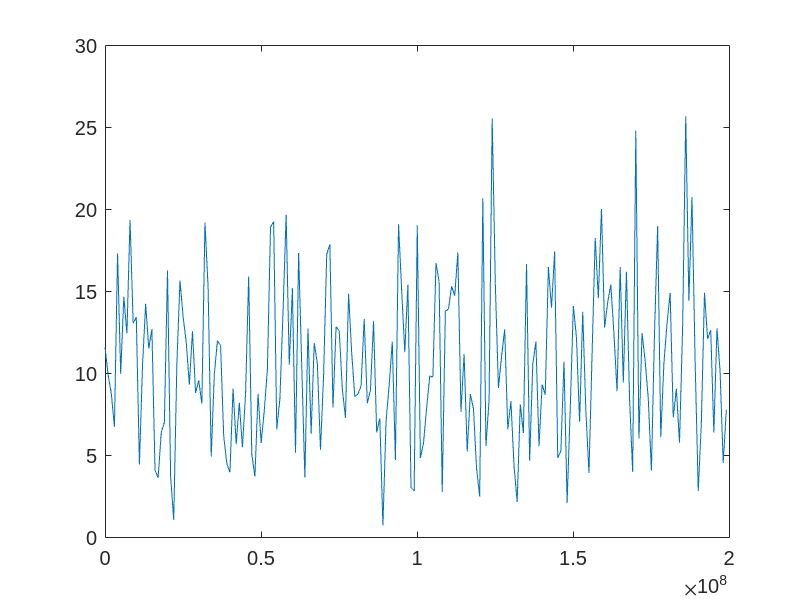

N = length(t);
y0 = abs(fft(data(N0+1:N0+N)));
f = (0:N-1)*Fs/N;
plot(f,y0);
% plot(abs(fftshift((fft(data(1:10000))))))
hold on 

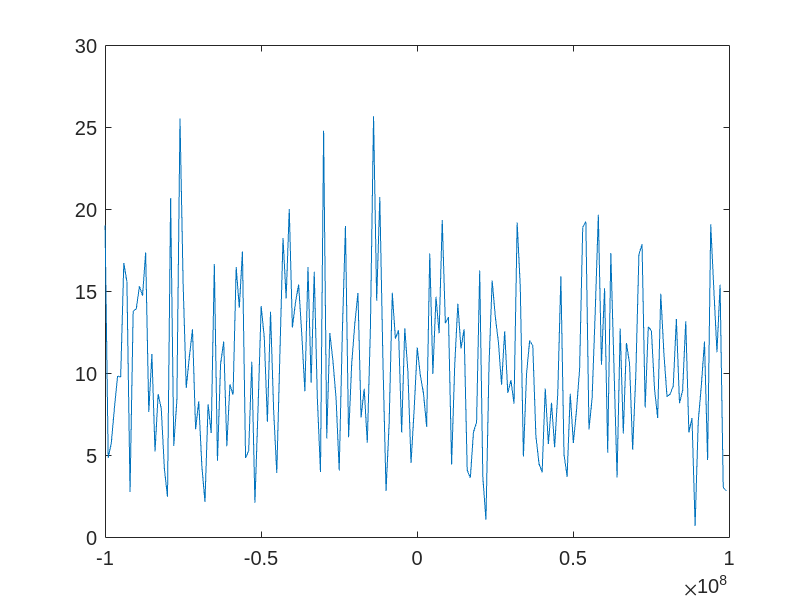


figure()
f1 = (0:N-1)*Fs/N-Fs/2;
y1 = abs(fftshift(fft(data(N0+1:N0+N))));
plot(f1,y1);
hold on

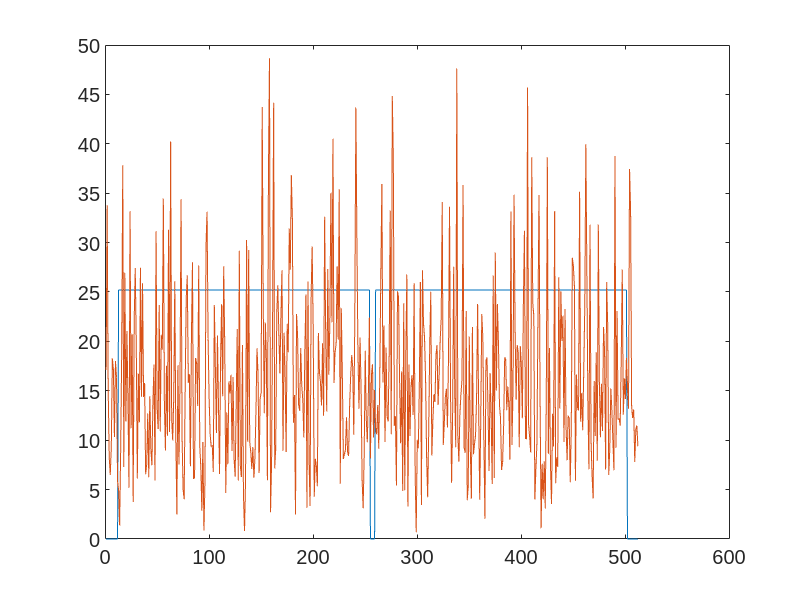


figure
cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
plot(abs(cfr_bb))
hold on

% decode part 
% freq shift
% fc = 5825e6;
% baseband_data = data.* exp(2*pi*1i*f_center*t);
% loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% data = data.*loc_carr;

pos = N0;
cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
plot(abs(cfr_recv))
hold on

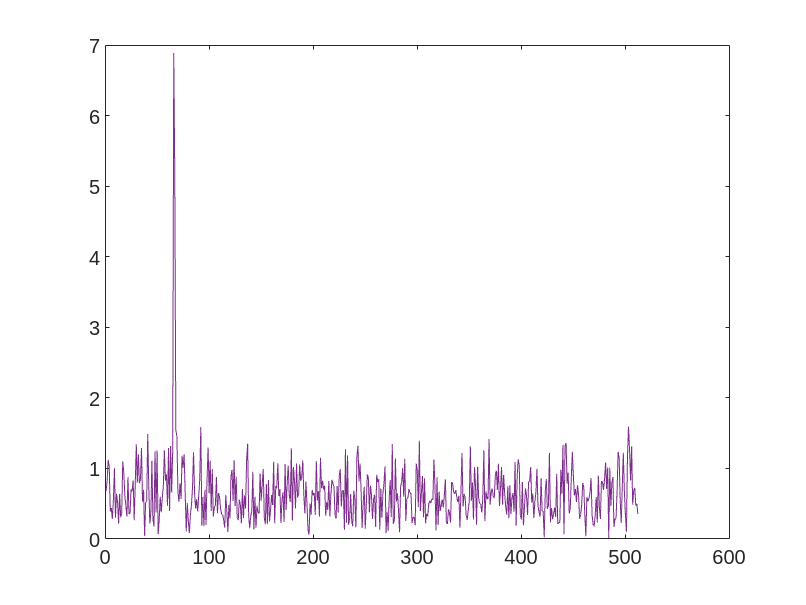

% plot(real(cfr_recv))
% hold on

cir1 = zeros(cfg.users, cfg.fftlen);

figure
for u=1:cfg.users
cir1(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(abs(cir1(1,:)))
hold on
end


% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
data = read_complex_binary('/mnt/tmp/usrp_heltf40_rx2.dat');
% data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf40_rx2.dat');
load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf40.mat")
load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF40_tx_bb.mat');

i = 2;
symbollen_table = [288, 576, 1152];
gilen_table = [32, 64, 128];
symbollen = symbollen_table(i);
gilen = gilen_table(i);


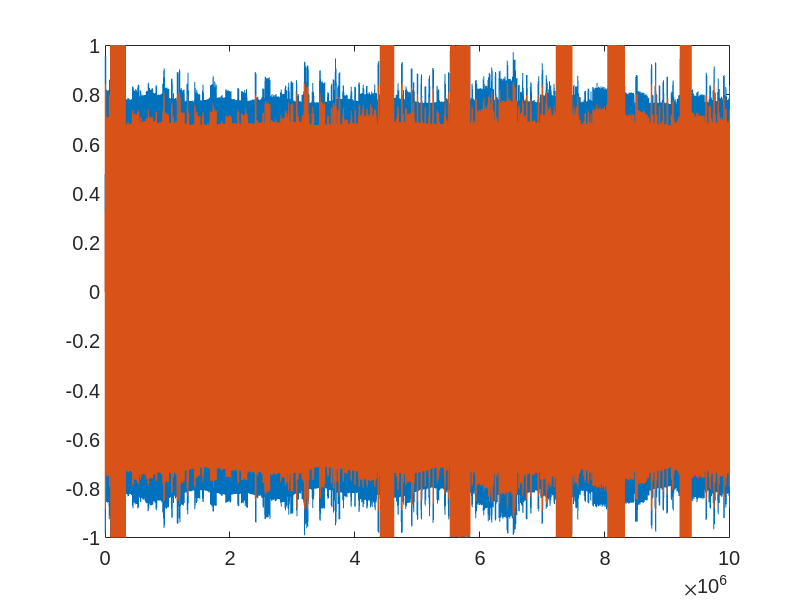

% time domain
N0 = 533;
figure
plot(real(data))
hold on
plot(imag(data))

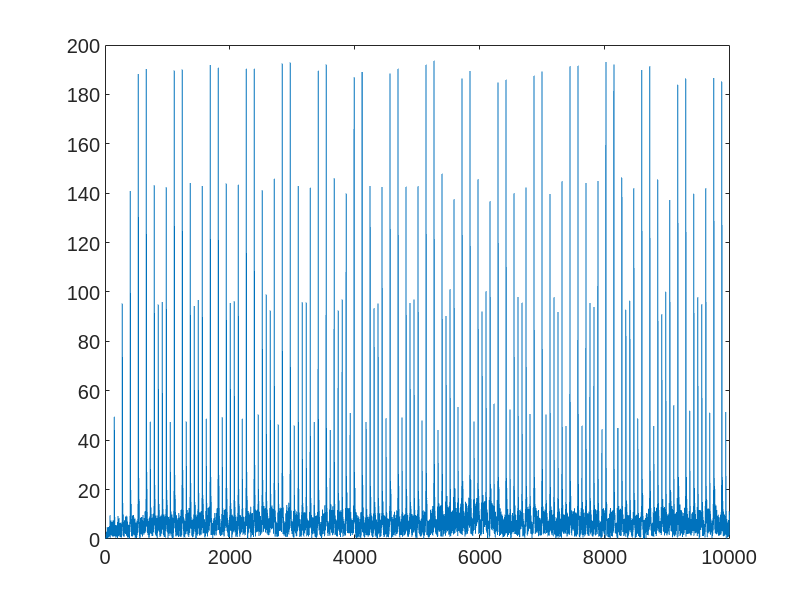

% plot(imag(data(N0+1:N0+288)))
% hold on 
% plot(real(bb(1,:))./ 1.5)
% hold on 


figure
corr_result = conv(data, bb(1,:));
plot(abs(corr_result(1:10000)))
hold on


% figure()
% Fs = 200e6;
% t = 0:1/Fs:0.000001-1/Fs % 1000 points
% N = length(t);
% y0 = abs(fft(data(N0+1:N0+N)));
% f = (0:N-1)*Fs/N;
% plot(f,y0);
% % plot(abs(fftshift((fft(data(1:10000))))))
% hold on 
% 
% figure()
% f1 = (0:N-1)*Fs/N-Fs/2;
% y1 = abs(fftshift(fft(data(N0+1:N0+N))));
% plot(f1,y1);
% hold on
% 
% figure
% cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
% plot(abs(cfr_bb))
% hold on

% % decode part 
% % freq shift
% % fc = 5825e6;
% % baseband_data = data.* exp(2*pi*1i*f_center*t);
% % loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% % data = data.*loc_carr;
% 
% pos = N0;
% cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
% plot(abs(cfr_recv))
% hold on
% % plot(real(cfr_recv))
% % hold on
% 
% row = 0
% num = 8000
% cir2 = zeros(cfg.users, cfg.fftlen);
% cir2(row,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% % 
% % figure
% % cir2(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% % plot(abs(cir2(1,:)))
% % hold on
% 
% figure
% for u=1:cfg.users
% cir2(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% plot(1:50:50*200,abs(cir2(1,1:200)))
% % plot(1:50:50*1024, abs(cir2(1,:)))
% hold on
% 
% end
% xlabel('Delay(ns)')
% ylabel('amplitude')
% title('CIR')

% decode part 
% freq shift
% fc = 5825e6;
% baseband_data = data.* exp(2*pi*1i*f_center*t);
% loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% data = data.*loc_carr;
row = 0;
num = 9000

num = 9000

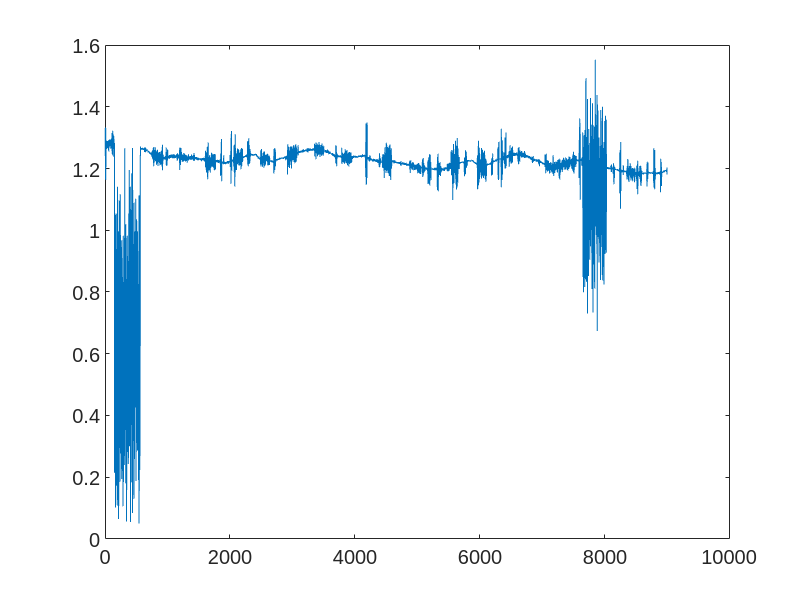

cir2 = zeros(num+1, cfg.fftlen);

for N = N0:symbollen:N0+num*symbollen
pos = N;
row = row+1;
cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';


t3 = 1:25:25*512;
cir2(row,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));

end


figure
plot(abs(cir2(:,63)))
hold on

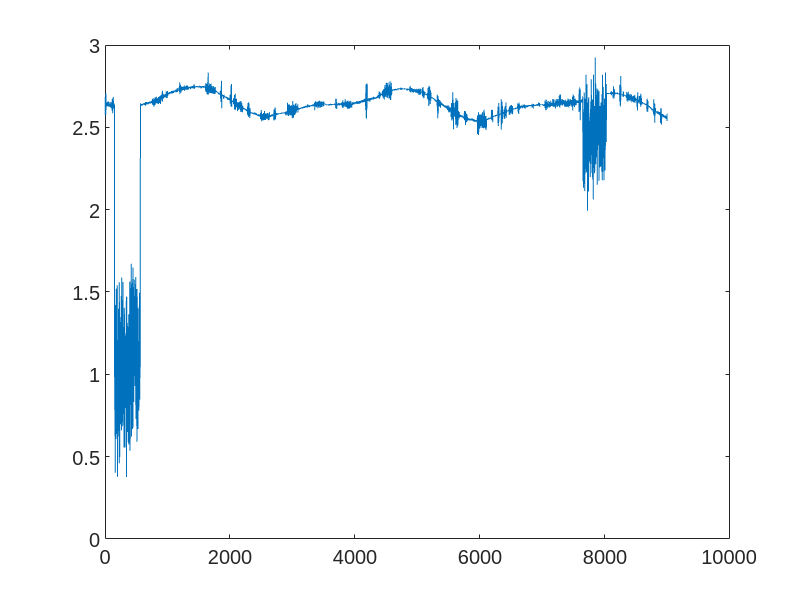


figure
plot(abs(cir2(:,64)))
hold on

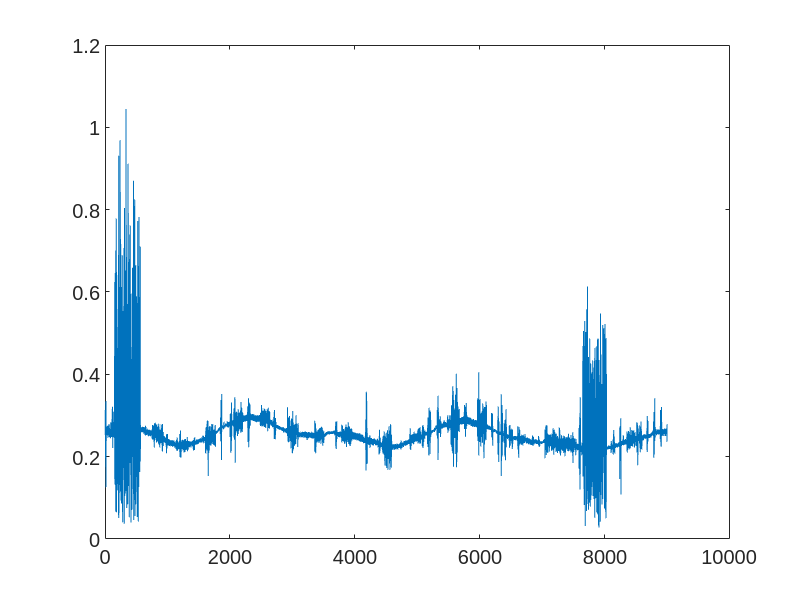


figure
plot(abs(cir2(:,65)))
hold on

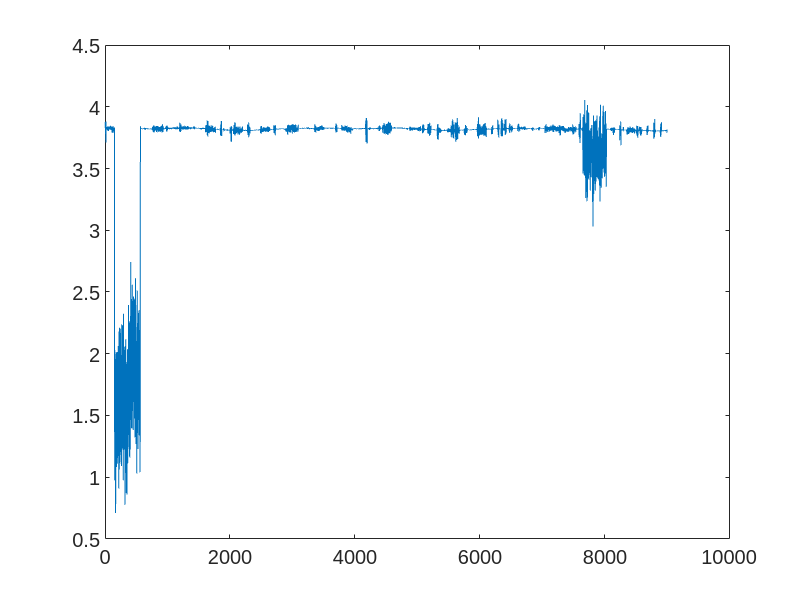


figure
plot(abs(cir2(:,66)))
hold on

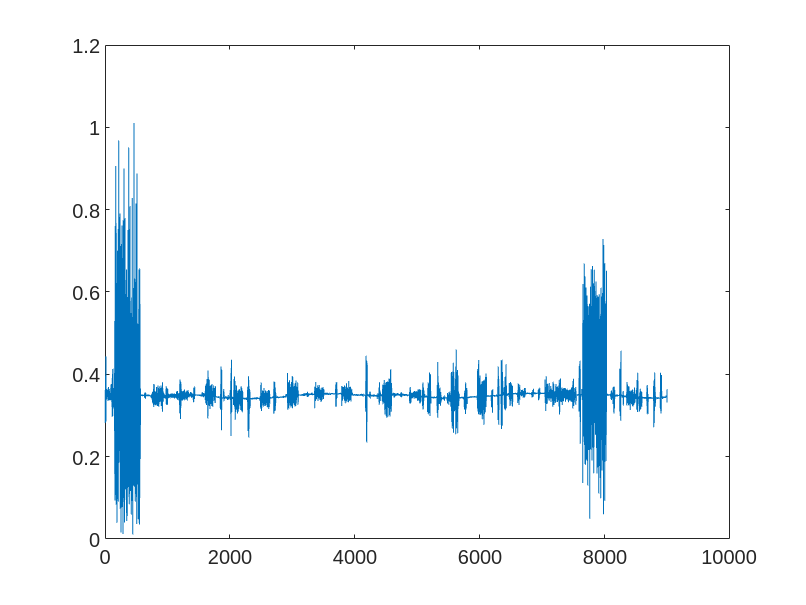


figure
plot(abs(cir2(:,67)))
hold on

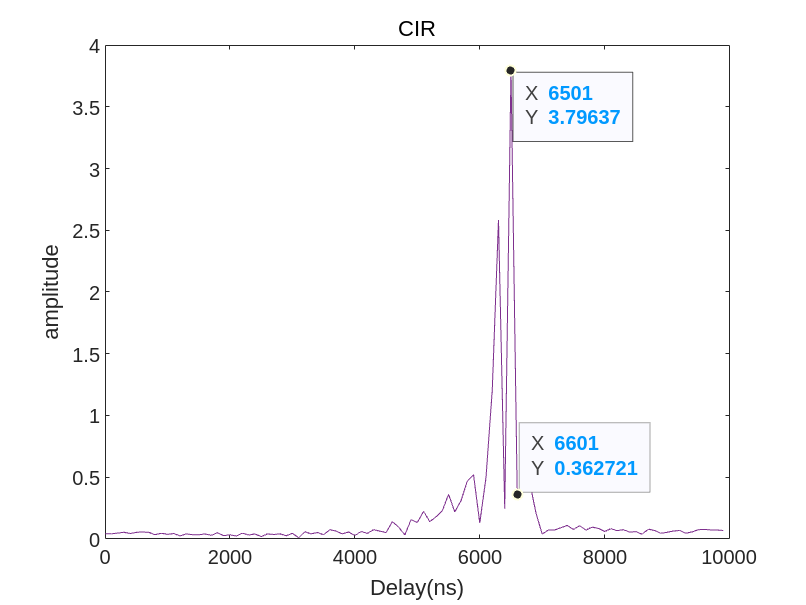



figure
for u=1:cfg.users
cir2(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
plot(1:100:100*100,abs(cir2(1,1:100)))
% plot(1:50:50*1024, abs(cir2(1,:)))
hold on

end
xlabel('Delay(ns)')
ylabel('amplitude')
title('CIR')